# 2021-01-02-Hailing

run_id = 'b30';

input_path = 'D:\2021-01-02-Hailing\';
gpu_block = [1024 1024 100 4 3];

useGPU = true;

curr_out_path = fullfile(input_path, 'output', run_id);

if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end
            
sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);

Pipeline Obj is generated...


sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
sdata = sdata.LoadRawImages('output_class', "cell");

====Loading raw images====
Loading round 1...[time = 117.47 s]
Loading round 2...[time = 116.33 s]
Loading round 3...[time = 115.71 s]
Collapsed to size 4624 by 1926 by 100
Collapsing round 1
Collapsing round 2
Collapsing round 3
Raw image as cell

sdata.rawImages = im_cell2mat(sdata.rawImages);
sdata = sdata.SwapChannels; % !!

====Swap Channels====
Channel 2 <==> Channel 3



% % Thresholding
% curr_bw = (50 > sdata.rawImages) & (sdata.rawImages > 0);
% sdata.rawImages(curr_bw) = 0;

% Preprocessing
sdata = sdata.HistEqualize('Method', "inter_round");

====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


sdata = sdata.HistEqualize('Method', "intra_round");

====Histogram Equalization====
Method: intra_round
Equalizing round 1
Equalizing round 2
Equalizing round 3


% sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);


gpu_overlap = 0;

NgpuBlock = 10

Completed [                    ]   0% --:--:--

gpu_idx =            1        1024
           1        1024


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=13.750899]
Shifted by -4 -8 -1
Round 3 vs. Round 1 finished [time=13.544419]
Shifted by -5 -10   0


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.91, C: 102279433[time = 18.34 s]
Get barcodes for Round 2....Q: 0.95, C: 87467722[time = 18.59 s]
Get barcodes for Round 3....Q: 0.93, C: 77559441[time = 19.02 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
[time = 152.01 s]
Number of spots found by barcode_test: 65772
[time = 152.88 s]


block_offsets =      0     0     0


====Block 1 Finished [time=253.534409]====

Completed [==                  ]  10% 00:38:02

gpu_idx =            1        1024
        1025        1926


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=13.695020]
Shifted by -4 -10  -1
Round 3 vs. Round 1 finished [time=13.132014]
Shifted by -4 -12   0


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.94, C: 91177648[time = 15.67 s]
Get barcodes for Round 2....Q: 0.97, C: 80698984[time = 16.99 s]
Get barcodes for Round 3....Q: 0.96, C: 73195591[time = 17.65 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 113.55 s]
Number of spots found by barcode_test: 36820
[time = 114.32 s]


block_offsets =         1024           0           0


====Block 2 Finished [time=208.488141]====

Completed [====                ]  20% 00:30:48

gpu_idx =         1025        2048
           1        1024


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=14.882188]
Shifted by -4 -7 -1
Round 3 vs. Round 1 finished [time=14.163011]
Shifted by -5 -10   0


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.90, C: 101754849[time = 18.65 s]
Get barcodes for Round 2....Q: 0.94, C: 85876374[time = 19.83 s]
Get barcodes for Round 3....Q: 0.91, C: 75052283[time = 20.39 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 135.34 s]
Number of spots found by barcode_test: 71565
[time = 136.17 s]


block_offsets =            0        1024           0


====Block 3 Finished [time=243.166613]====

Completed [======              ]  30% 00:27:26

gpu_idx =         1025        2048
        1025        1926


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=13.461313]
Shifted by -4 -9 -1
Round 3 vs. Round 1 finished [time=12.768127]
Shifted by -4 -12  -1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.93, C: 90763110[time = 16.07 s]
Get barcodes for Round 2....Q: 0.97, C: 79123251[time = 17.50 s]
Get barcodes for Round 3....Q: 0.95, C: 70256170[time = 17.43 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 119.11 s]
Number of spots found by barcode_test: 44972
[time = 119.88 s]


block_offsets =         1024        1024           0


====Block 4 Finished [time=213.320845]====

Completed [========            ]  40% 00:22:58

gpu_idx =         2049        3072
           1        1024


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=14.967548]
Shifted by -5 -6 -1
Round 3 vs. Round 1 finished [time=14.230693]
Shifted by -6 -9 -1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.89, C: 101568181[time = 18.62 s]
Get barcodes for Round 2....Q: 0.94, C: 85271004[time = 20.59 s]
Get barcodes for Round 3....Q: 0.91, C: 73457132[time = 20.57 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 159.66 s]
Number of spots found by barcode_test: 72395
[time = 160.44 s]


block_offsets =            0        2048           0


====Block 5 Finished [time=267.774301]====

Completed [==========          ]  50% 00:19:46

gpu_idx =         2049        3072
        1025        1926


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=13.380215]
Shifted by -5 -9 -1
Round 3 vs. Round 1 finished [time=13.608092]
Shifted by -5 -12  -1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.92, C: 90281888[time = 16.09 s]
Get barcodes for Round 2....Q: 0.96, C: 77436188[time = 17.58 s]
Get barcodes for Round 3....Q: 0.93, C: 67553143[time = 17.81 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 116.53 s]
Number of spots found by barcode_test: 53237
[time = 117.25 s]


block_offsets =         1024        2048           0


====Block 6 Finished [time=212.172995]====

Completed [============        ]  60% 00:15:32

gpu_idx =         3073        4096
           1        1024


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=14.910770]
Shifted by -5 -4 -1
Round 3 vs. Round 1 finished [time=14.272771]
Shifted by -6 -8 -1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.91, C: 102174697[time = 18.30 s]
Get barcodes for Round 2....Q: 0.95, C: 86628879[time = 19.75 s]
Get barcodes for Round 3....Q: 0.92, C: 75409419[time = 20.61 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 135.98 s]
Number of spots found by barcode_test: 63011
[time = 136.78 s]


block_offsets =            0        3072           0


====Block 7 Finished [time=242.741197]====

Completed [==============      ]  70% 00:11:43

gpu_idx =         3073        4096
        1025        1926


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=13.213909]
Shifted by -5 -8 -1
Round 3 vs. Round 1 finished [time=12.873248]
Shifted by -6 -11  -1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.92, C: 90306971[time = 16.00 s]
Get barcodes for Round 2....Q: 0.96, C: 77395965[time = 17.84 s]
Get barcodes for Round 3....Q: 0.93, C: 67216313[time = 17.65 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 115.78 s]
Number of spots found by barcode_test: 53218
[time = 116.52 s]


block_offsets =         1024        3072           0


====Block 8 Finished [time=210.541529]====

Completed [================    ]  80% 00:07:43

gpu_idx =         4097        4624
           1        1024


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=8.199139]
Shifted by -5 -4 -1
Round 3 vs. Round 1 finished [time=7.951314]
Shifted by -6 -7  1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.93, C: 52971477[time = 9.40 s]
Get barcodes for Round 2....Q: 0.96, C: 45822096[time = 9.75 s]
Get barcodes for Round 3....Q: 0.94, C: 41082775[time = 10.29 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 68.40 s]
Number of spots found by barcode_test: 22131
[time = 68.76 s]


block_offsets =            0        4096           0


====Block 9 Finished [time=125.389748]====

Completed [==================  ]  90% 00:03:40

gpu_idx =         4097        4624
        1025        1926


Pipeline Obj is generated...


====Global Registration====
Round 2 vs. Round 1 finished [time=7.377686]
Shifted by -5 -7 -1
Round 3 vs. Round 1 finished [time=7.309628]
Shifted by -6 -10  -1


====Spot Finding====
Method: barcode_test
Reference round: 1
Get barcodes for Round 1....Q: 0.91, C: 46434761[time = 8.07 s]
Get barcodes for Round 2....Q: 0.95, C: 39420397[time = 8.80 s]
Get barcodes for Round 3....Q: 0.93, C: 33607604[time = 8.91 s]
The global quality score threshold for barcode calling is: 0.03 
Iterate through clusters...[time = 60.42 s]
Number of spots found by barcode_test: 25770
[time = 60.83 s]


block_offsets =         1024        4096           0


====Block 10 Finished [time=111.162366]====

Completed [====================] Done. [2088 seconds]


gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
NgpuBlock = numel(gb_idx)
upd = textprogressbar(NgpuBlock, 'updatestep', 1);

tile_goodSpots = [];
tile_goodReads = [];
tile_score = [];
tile_counts = 0;

for i =1:NgpuBlock
    
    bdata_start = tic;
    gpu_idx = gb_idx{i}
    
    fprintf(sdata.log, sprintf("====Current Block: %d====\n", i));
    fprintf(sdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
    
    bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    bdata.log = sdata.log;
    bdata = bdata.LoadDim(gpu_block);
    bdata.rawImages = sdata.rawImages(...
        gpu_idx(1,1):gpu_idx(1,2),...
        gpu_idx(2,1):gpu_idx(2,2),...
        :,:,:);
    
    bdata = bdata.test_GlobalRegistration('useGPU', true);
%     bdata = bdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
    
    % replace the old image 
    sdata.rawImages(...
        gpu_idx(1,1):gpu_idx(1,2),...
        gpu_idx(2,1):gpu_idx(2,2),...
        :,:,:) = bdata.registeredImages;
    
%     bdata = bdata.LoadCodebook;
    bdata = bdata.SpotFinding('Method', "barcode_test", 'ref_index', 1,  'qualityThreshold', 0.01, ...
            'volumeThreshold', 30, 'barcodeMethod', "iteration", 'showPlots', false);
%     bdata = bdata.ReadsExtraction('showPlots', false, 'voxelSize', [1 1 1]); 
%     bdata = bdata.ReadsFiltration('showPlots', false);
    
    block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
    if size(bdata.allSpots, 1) ~= 0
        block_offsets = repmat(block_offsets, size(bdata.allSpots, 1), 1);
        bdata.allSpots = bdata.allSpots + int16(block_offsets);
    end
    
    % Update tile reads
    tile_goodSpots = [tile_goodSpots; bdata.allSpots];
    tile_goodReads = [tile_goodReads; bdata.allReads];
    tile_score = [tile_score; bdata.FilterScores];
    tile_counts = tile_counts + size(bdata.allSpots, 1);
    
    fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
    upd(i);
end

% Save registered image
output_dir = fullfile(curr_out_path, 'registered_image');
if ~exist(output_dir, 'dir')
   mkdir(output_dir);
end
new_SaveImg(output_dir, sdata.rawImages);

Saving images to D:Б-01-02-HailingRound 1 finished...[time=26.744070]
Round 2 finished...[time=48.080116]
Round 3 finished...[time=72.276525]




% Save tile points 
save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'tile_goodReads', 'tile_goodSpots');

reset(gpuDevice)

fclose(sdata.log);

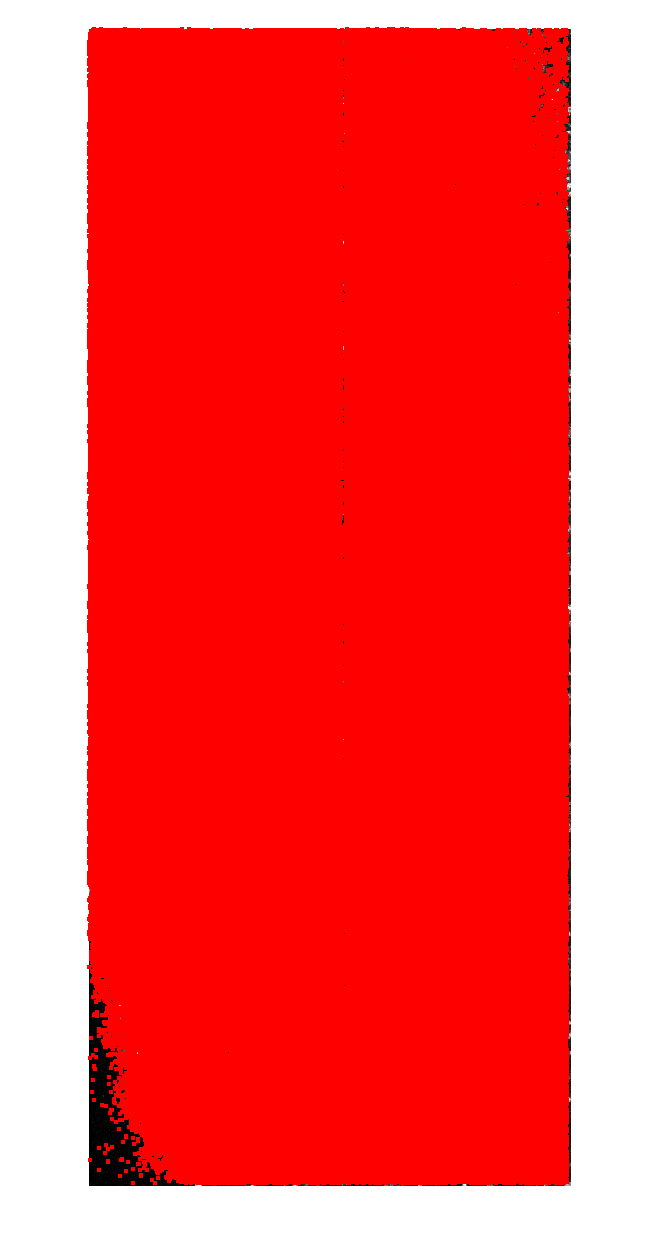

img_path = fullfile('D:/2021-01-02-Hailing/round1/TileScan 001_TileScan_001_Merging_z00_ch04.tif');
img = new_LoadMultipageTiff(img_path, 'uint8', 'uint8', false);
img = img(:,:,50:60);
img = max(img, [], 3);

plot_centroids(tile_goodSpots, img, 10)

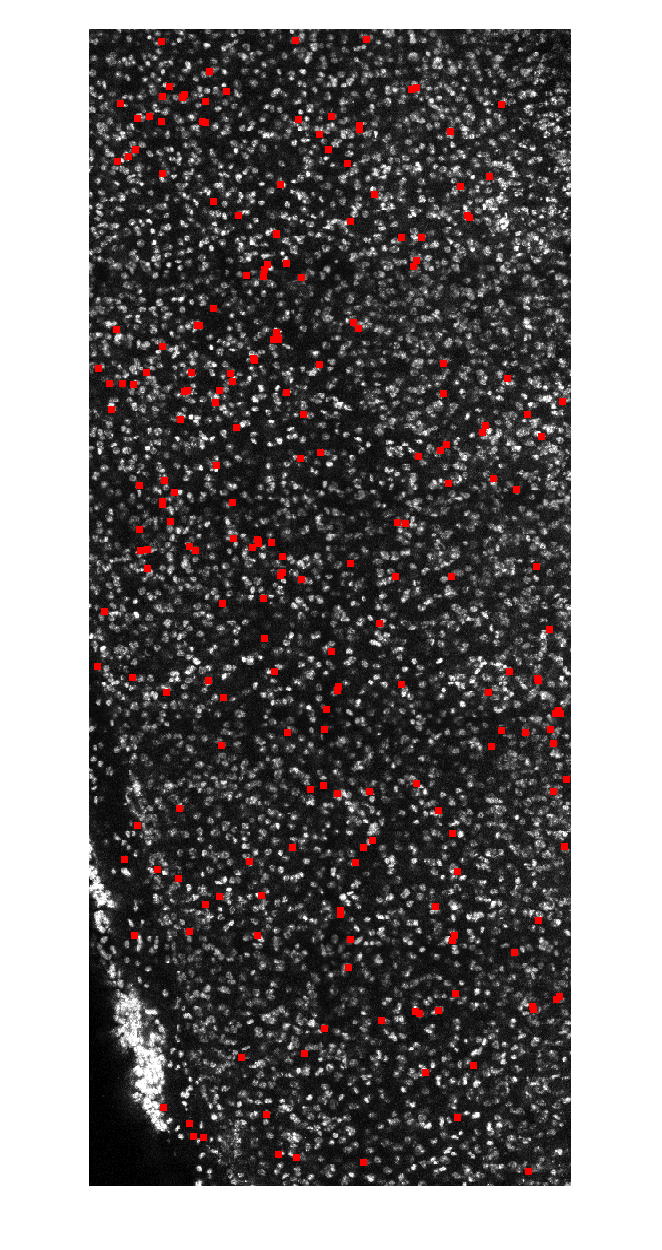


current_index = ismember(tile_goodReads, '123');
current_spots = tile_goodSpots(current_index, :);

current_spots = current_spots(ismember(current_spots(:,3), [50:60]),:);

plot_centroids(current_spots, img, 15)